Parameter

theta2 = sym('theta_2');   theta3 = sym('theta_3');   theta4 = sym('theta_4');
theta5 = sym('theta_5');   theta6 = sym('theta_6');
Dxs = sym('D_x');          Dys = sym('D_y');           
O1_x =  45;   O1_y = 0;        
O2_x =   0;   O2_y = 0;
O3_x =   0;   O3_y = 45;
O3C = 40;   O1A = 25;   O2B = 20;   BA = 45;   AD = 40;   DC = 65;   DF = 70;   
bend = 120*pi/180;            
q0   = 105*pi/180;             
rpm  = 10;    rot = -1;       
omega4 = rot*2*pi*rpm/60;     
T  = 60/rpm;                 
t0 = 0;                       
Torque = 3;                    
th    = q0 + rot*deg2rad(0:4:360);            
th_st = deg2rad(101.87 + rot*(-90:3:90));      

Equation

Bx = O2_x + O2B*cos(theta4);         By = O2_y + O2B*sin(theta4);         
Ax = O1_x + O1A*cos(theta3);         Ay = O1_y + O1A*sin(theta3);         
Dx = Bx + (BA+AD)*cos(theta5);       Dy = By + (BA+AD)*sin(theta5);        
Cx = O3_x + O3C*cos(theta2);         Cy = O3_y + O3C*sin(theta2);         
Fx = Dx + DF*cos(theta6+bend);       Fy = Dy + DF*sin(theta6+bend);       
eq1 = Ax == Bx + BA*cos(theta5);     eq2 = Ay == By + BA*sin(theta5);      
eq3 = Cx == Dxs + DC*cos(theta6);    eq4 = Cy == Dys + DC*sin(theta6);     
sol1 = solve([eq1 eq2],[theta3 theta5]);
sol2 = solve([eq3 eq4],[theta2 theta6]);

[~,k1] = max(real(double(subs(sin(sol1.theta_3),theta4,q0))));            
theta3_sol = sol1.theta_3(k1);       theta5_sol = sol1.theta_5(k1);
DxNew = subs(Dx,theta5,theta5_sol);  DyNew = subs(Dy,theta5,theta5_sol);
[~,k2] = max(real(double(subs(sin(sol2.theta_2),[Dxs Dys],subs([DxNew DyNew],theta4,q0)))));  
theta2_sol = sol2.theta_2(k2);       theta6_sol = sol2.theta_6(k2);
S = @(s) subs(s,[theta2 theta3 theta5 theta6],[theta2_sol theta3_sol theta5_sol theta6_sol]);
AxNew = S(Ax);   AyNew = S(Ay);     
CxNew = S(Cx);   CyNew = S(Cy);      
FxNew = S(Fx);   FyNew = S(Fy);    
Dxn = @(a) real(double(subs(DxNew,theta4,a)));
Dyn = @(a) real(double(subs(DyNew,theta4,a)));
N   = @(G,a) real(double(subs(G,{theta4,Dxs,Dys},{a,Dxn(a),Dyn(a)})));

Animation

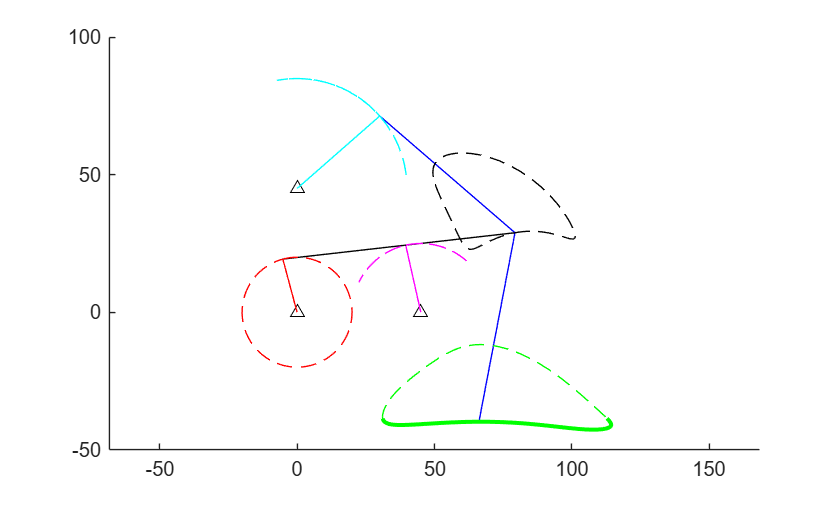

th4 = @(t) q0 + omega4*t;           
h_link4 = @(t) plot([O2_x N(Bx,th4(t))],[O2_y N(By,th4(t))],"-r");
h_link3 = @(t) plot([O1_x N(AxNew,th4(t))],[O1_y N(AyNew,th4(t))],"-m");
h_link5 = @(t) plot(N([Bx AxNew DxNew],th4(t)),N([By AyNew DyNew],th4(t)),"-k");
h_link2 = @(t) plot([O3_x N(CxNew,th4(t))],[O3_y N(CyNew,th4(t))],"-c");
h_link6 = @(t) plot(N([CxNew DxNew FxNew],th4(t)),N([CyNew DyNew FyNew],th4(t)),"-b");
figure
hold on
plot([O1_x O2_x O3_x],[O1_y O2_y O3_y],"k^")
fanimator(h_link4,"AnimationRange",[0 T])
fanimator(h_link3,"AnimationRange",[0 T])
fanimator(h_link5,"AnimationRange",[0 T])
fanimator(h_link2,"AnimationRange",[0 T])
fanimator(h_link6,"AnimationRange",[0 T])
plot(N(Bx,th),N(By,th),"--r")
plot(N(AxNew,th),N(AyNew,th),"--m")
plot(N(DxNew,th),N(DyNew,th),"--k")
plot(N(CxNew,th),N(CyNew,th),"--c")
plot(N(FxNew,th),N(FyNew,th),"--g")
plot(N(FxNew,th_st),N(FyNew,th_st),"-g","LineWidth",2)     
axis equal
hold off

playAnimation

Velocity image / Acceleration image 

dDx = diff(DxNew,theta4);   dDy = diff(DyNew,theta4);
dth = @(G) diff(G,theta4) + diff(G,Dxs)*dDx + diff(G,Dys)*dDy;     
P   = [AxNew AyNew; Bx By; CxNew CyNew; DxNew DyNew; FxNew FyNew]; 
V   = dth(P)*omega4;       
Acc = dth(V)*omega4;        
a0 = q0 + omega4*t0;        
P0 = N(P,a0);
V0 = N(V,a0)              

V0 =    20.3288    4.5529
   20.2303    5.4207
    8.6460   -9.8575
   20.4164    3.7815
   39.4747    0.1480


A0 = N(Acc,a0)             

A0 =     5.1431  -16.6378
    5.6765  -21.1851
    8.3217  -16.0059
    4.6690  -12.5957
    5.8827   -7.3528


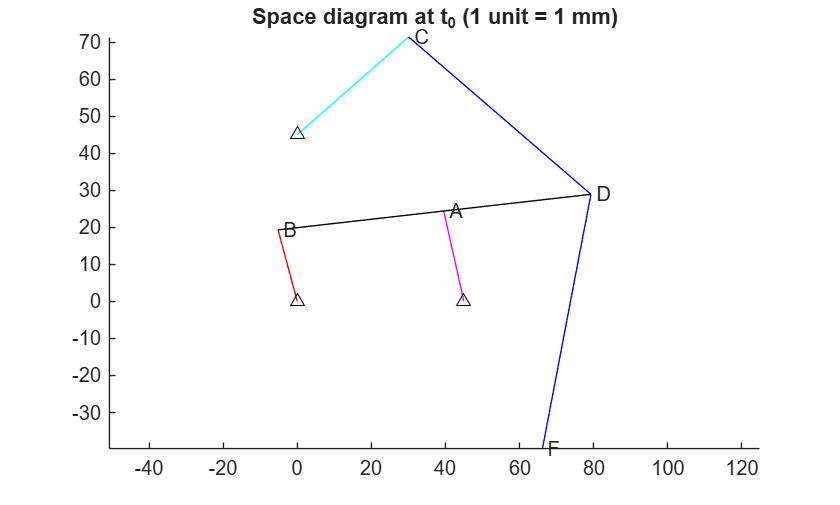

name = {' a',' b',' c',' d',' f'};
figure; hold on             
plot([O2_x P0(2,1)],[O2_y P0(2,2)],"-r",[O1_x P0(1,1)],[O1_y P0(1,2)],"-m",P0([2 1 4],1),P0([2 1 4],2),"-k")
plot([O3_x P0(3,1)],[O3_y P0(3,2)],"-c",P0([3 4 5],1),P0([3 4 5],2),"-b",[O1_x O2_x O3_x],[O1_y O2_y O3_y],"k^")
text(P0(:,1),P0(:,2),upper(name));   axis equal;   title("Space diagram at t_0 (1 unit = 1 mm)")

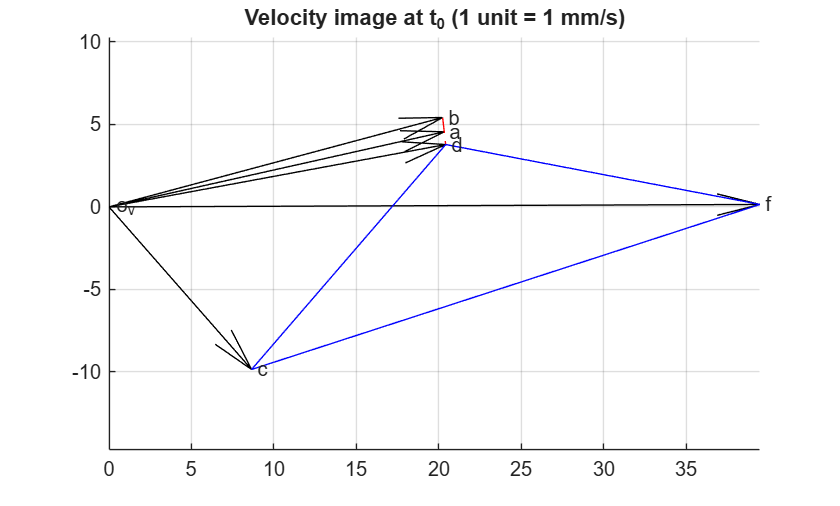

figure; hold on           
quiver(zeros(5,1),zeros(5,1),V0(:,1),V0(:,2),0,"k")                 
plot(V0([2 1 4],1),V0([2 1 4],2),"--r")                              
plot(V0([3 4 5 3],1),V0([3 4 5 3],2),"-b")                          
text(V0(:,1),V0(:,2),name);   text(0,0," o_v");   axis equal;   grid on
title("Velocity image at t_0 (1 unit = 1 mm/s)")

figure; hold on            
quiver(zeros(5,1),zeros(5,1),A0(:,1),A0(:,2),0,"k")                 
plot(A0([2 1 4],1),A0([2 1 4],2),"--r")                             
plot(A0([3 4 5 3],1),A0([3 4 5 3],2),"-b")                          
r  = [P0(1,:)-[O1_x O1_y]; P0(1,:)-P0(2,:); P0(3,:)-[O3_x O3_y]; P0(3,:)-P0(4,:)];
vr = [V0(1,:); V0(1,:)-V0(2,:); V0(3,:); V0(3,:)-V0(4,:)];
ar = [A0(1,:); A0(1,:)-A0(2,:); A0(3,:); A0(3,:)-A0(4,:)];
w  = (r(:,1).*vr(:,2) - r(:,2).*vr(:,1))./(r(:,1).^2 + r(:,2).^2)   

w =    -0.8333
   -0.0194
   -0.3278
    0.2772


al = (r(:,1).*ar(:,2) - r(:,2).*ar(:,1))./(r(:,1).^2 + r(:,2).^2)   

al =    -0.0553
    0.1017
   -0.4380
    0.0030


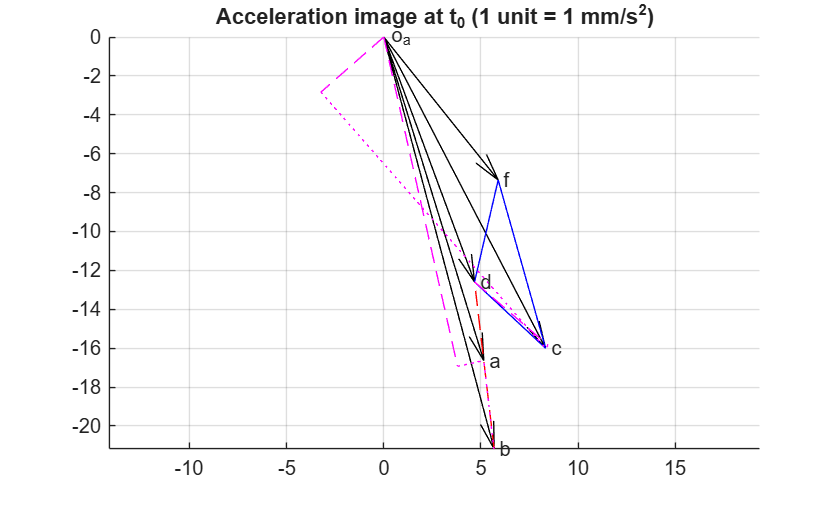

s  = [0 0; A0(2,:); 0 0; A0(4,:)];                                 
n  = s - w.^2.*r;                                                   
plot([s(:,1) n(:,1)]',[s(:,2) n(:,2)]',"--m")
plot([n(:,1) A0([1 1 3 3],1)]',[n(:,2) A0([1 1 3 3],2)]',":m")
text(A0(:,1),A0(:,2),name);   text(0,0," o_a");   axis equal;   grid on
title("Acceleration image at t_0 (1 unit = 1 mm/s^2)")

Velocity Acceleration Force graph

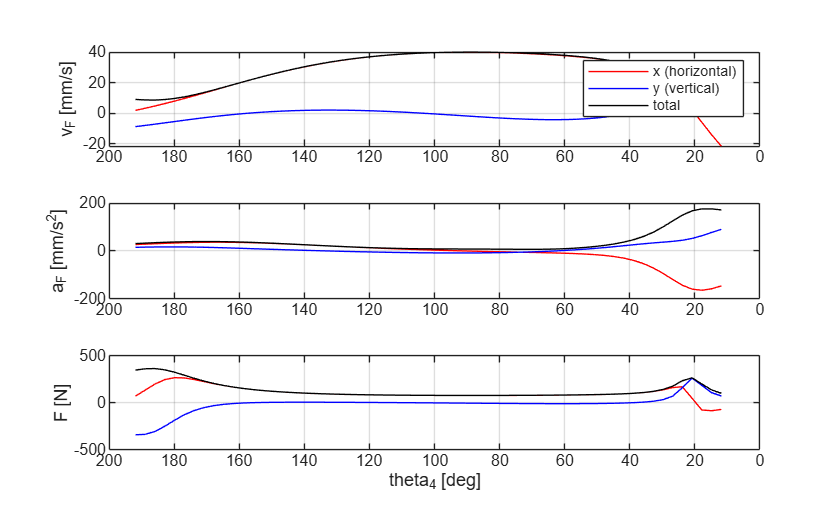

th_deg = rad2deg(th_st);                             
vF   = [N(V(5,1),th_st); N(V(5,2),th_st)];          
aF   = [N(Acc(5,1),th_st); N(Acc(5,2),th_st)];      
vAbs = sqrt(vF(1,:).^2 + vF(2,:).^2);
aAbs = sqrt(aF(1,:).^2 + aF(2,:).^2);
FAbs = Torque*abs(omega4)./(vAbs/1000);              
FF   = FAbs.*vF./vAbs;                              
figure
subplot(3,1,1); plot(th_deg,vF(1,:),"-r",th_deg,vF(2,:),"-b",th_deg,vAbs,"-k"); grid on; ylabel("v_F [mm/s]")
legend("x (horizontal)","y (vertical)","total")
subplot(3,1,2); plot(th_deg,aF(1,:),"-r",th_deg,aF(2,:),"-b",th_deg,aAbs,"-k"); grid on; ylabel("a_F [mm/s^2]")
subplot(3,1,3); plot(th_deg,FF(1,:),"-r",th_deg,FF(2,:),"-b",th_deg,FAbs,"-k"); grid on; ylabel("F [N]")
xlabel("theta_4 [deg]")
if rot == -1, set(findall(gcf,"Type","axes"),"XDir","reverse"), end   

th_deg = rad2deg(th_st);                                 
Fx_st  = N(FxNew,th_st);                                
stroke = max(Fx_st) - min(Fx_st);                        
[~, iv] = max(abs(vF(1,:)));   max_vF = vF(1,iv);       
[~, ia] = max(abs(aF(1,:)));   max_aF = aF(1,ia);       
[min_F, iF] = min(FAbs);                                
theta_at = th_deg([iv ia iF]);                          
fprintf("stroke = %.2f mm\n", stroke)

stroke = 83.11 mm


fprintf("max_vFx, Deg = %.2f mm/s, %.2f deg\n", [max_vF, theta_at(1)])

max_vFx, Deg = 40.17 mm/s, 89.87 deg


fprintf("max_aFx, Deg = %.2f mm/s^2, %.2f deg\n", [max_aF, theta_at(2)])

max_aFx, Deg = -164.97 mm/s^2, 17.87 deg


fprintf("min_F, Deg = %.2f N, %.2f deg\n", [min_F, theta_at(3)])

min_F, Deg = 78.12 N, 89.87 deg
